% This script demonstrates the controller synthesis algorithm that is based
% on optimal control in generator space on the turn left maneuver of a
% ship

% load benchmark parameters
Param = param_ship();

% define algorithm options
Opts = [];

Opts.N = 1;                               % number of time steps
Opts.Ninter = 35;                         % number of intermediate steps
Opts.reachSteps = 30;                     % number of reachability steps
Opts.Q = diag([1,1,110,10,10,20]);        % state weighting matrix
Opts.R = 0*eye(3);                        % input weighting matrix
Opts.refTraj.Q = diag([1 1 100 50 1 1]);  % state weighting mat. (ref traj)
Opts.cora.alg = 'poly';                   % reachability algorithm
Opts.cora.tensorOrder = 3;                % tensor order for reachability

% controller synthesis
clock = tic;
[objContr,res] = generatorSpaceControl('ship',Param, Opts);

Time step: 1


tComp = toc(clock);

disp([newline,'Computation time: ',num2str(tComp),'s']);


Computation time: 162.0705s


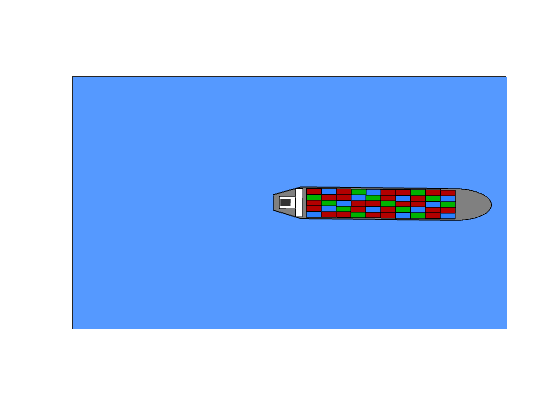


% simulation 
[resSim,~,~] = simulateRandom(objContr);

% animation
speedUp = 5;
animate(resSim,'ship',[],[],[],speedUp);

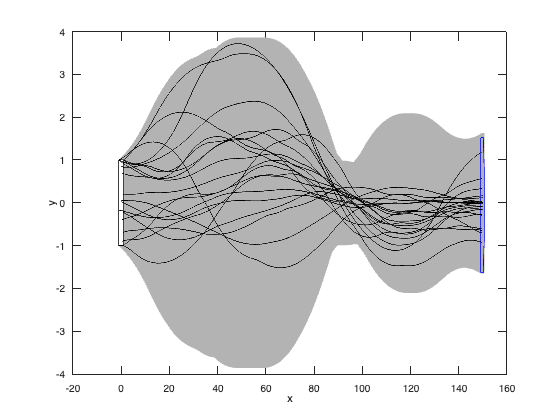


% visualization
figure; hold on; box on
plotReach(res,[1,2],[.7 .7 .7]);
plotReachTimePoint(res,[1,2],'b');
plot(Param.R0,[1,2],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[1,2],'k');
xlabel('x'); ylabel('y');

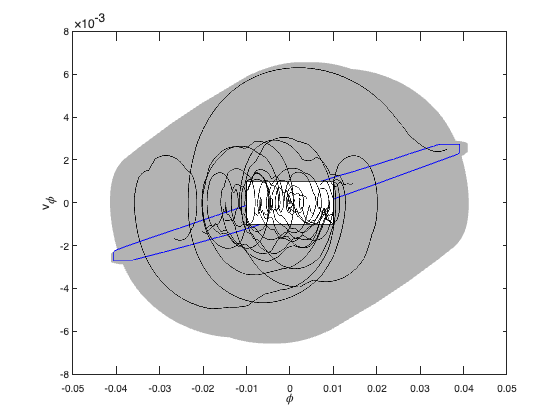


figure; hold on; box on
plotReach(res,[3,6],[.7 .7 .7]);
plotReachTimePoint(res,[3,6],'b');
plot(Param.R0,[3,6],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[3,6],'k');
xlabel('\phi'); ylabel('v_\phi');

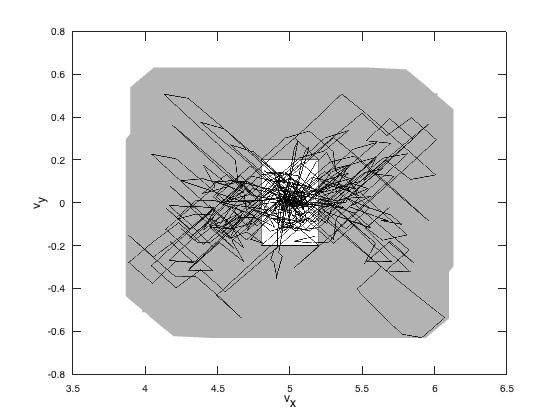


figure; hold on; box on
plotReach(res,[4,5],[.7 .7 .7]);
plotReachTimePoint(res,[4,5],'b');
plot(Param.R0,[4,5],'FaceColor','w','EdgeColor','k');
plotSimulation(resSim,[4,5],'k');
xlabel('v_x'); ylabel('v_y');